# Attacking Subsystem- Performance Evaluation for spoofing target accuracy

## Initialize the Evaluation Script

clear;
c = clock;
seed = floor(sum(c));
rng(seed);
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
file_path = "20MHz_USRP_500us.json";

%set the configuration path
config_path = david_path + file_path;

### Generate Test Ranges and Velocities

valid_ranges = [60,200];
valid_velocities = [1,25];
num_cases = 150;

[spoof_ranges,spoof_velocities] = characterization_functions.initialize_USRP_attack_subsystem_test_cases( ...
                num_cases, ...
                valid_ranges, ...
                valid_velocities);

### Save data needed by the USRP to a file

%save the chirp to a file
characterization_functions.save_USRP_attack_subsystem_chirp_to_file( ...
    config_path);

velocity_file_path = "/home/david/Documents/MATLAB_generated/MATLAB_desired_spoof_velocities/";
range_file_path = "/home/david/Documents/MATLAB_generated/MATLAB_desired_spoof_ranges/";

characterization_functions.save_desired_spoofing_ranges_and_velocities_to_file( ...
    spoof_velocities,...
    velocity_file_path, ...
    spoof_ranges,...
    range_file_path)

## Run Evaluation on USRP

NOTE: Ensure that realistic movement, FN attacks, and Jamming are disabled on the attacking subsystem

### Process the received data

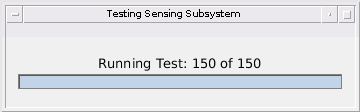

test_data_spoofing_performance = 1.0e+03 *

    0.1379    0.0188    0.1423    0.0225    0.0043    0.0037
    0.1379    0.0188    0.1454    0.0224    0.0075    0.0037
    0.1379    0.0188    0.1445    0.0224    0.0065    0.0037
    0.1379    0.0188    0.1437    0.0225    0.0058    0.0037
    0.1379    0.0188    0.1424    0.0225    0.0045    0.0037
    0.1379    0.0188    0.1356    0.0225    0.0023    0.0037
    0.1379    0.0188    0.1469    0.0225    0.0090    0.0037
    0.1379    0.0188    0.1462    0.0225    0.0082    0.0037
    0.1379    0.0188    0.1451    0.0225    0.0072    0.0037
    0.1379    0.0188    0.1444    0.0225    0.0065    0.0037


save_file_name = "attack_subsystem_spoofing_performance";
frames_to_compute = 40;
attack_start_frame = 14;
num_attack_frames = 15;

test_data_spoofing_performance = ...
                characterization_functions.USRP_get_spoofing_test_results( ...
                    num_cases, ...
                    frames_to_compute, ...
                    attack_start_frame, ...
                    num_attack_frames, ...
                    spoof_ranges, ...
                    spoof_velocities, ...
                    config_path, ...
                    save_file_name)

### Plot Test Case Information

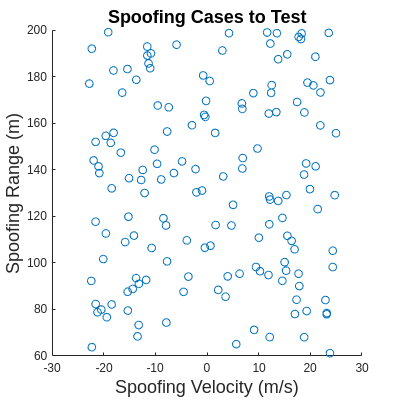

read_file_name = save_file_name + ".csv";
characterization_functions.plot_spoofing_test_configurations(read_file_name);

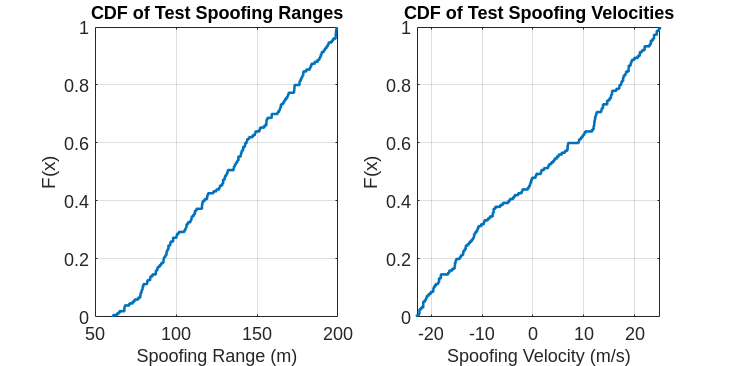

characterization_functions.plot_spoofing_test_configuration_cdfs(read_file_name);

### Plot Test Case Results

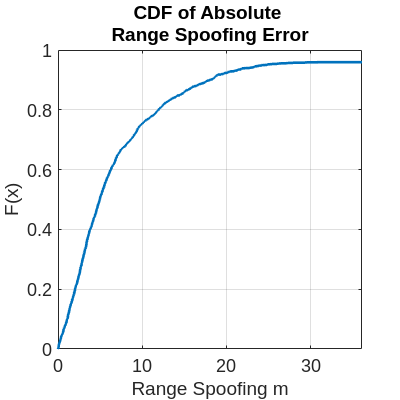

ans = 1×5 table
    Mean (m)    Variance (m)^2    MSE (m)^2    90th Percentile (m)    Percent Failed Trials
    ________    ______________    _________    ___________________    _____________________

     12.792         1489.1         1652.1            18.046                     0          


% plot Range Spoofing Error
actual_values_idx = 1;
estimated_values_idx = 3;
abs_errors_idx = 5;
metric_title = "Range Spoofing";
metric_units = "m";
percentile = 90;
scale_factor = 1;
characterization_functions.generate_testing_summary_absolute_error(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)

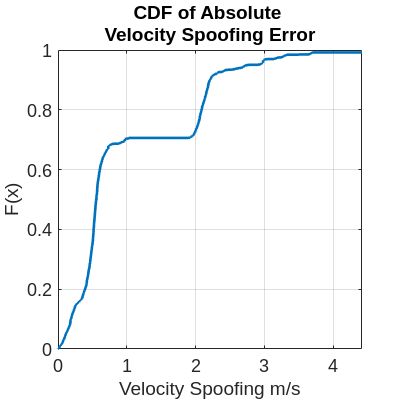

ans = 1×5 table
    Mean (m/s)    Variance (m/s)^2    MSE (m/s)^2    90th Percentile (m/s)    Percent Failed Trials
    __________    ________________    ___________    _____________________    _____________________

      1.1266           3.3042           4.5719               2.209                      0          


%Summary of Spoofing Velocity Performance
actual_values_idx = 2;
estimated_values_idx = 4;
abs_errors_idx = 6;
metric_title = "Velocity Spoofing";
metric_units = "m/s";
percentile = 90;
scale_factor = 1;
characterization_functions.generate_testing_summary_absolute_error(read_file_name,...
    actual_values_idx, ...
    estimated_values_idx, ...
    abs_errors_idx, ...
    metric_title, ...
    metric_units,...
    percentile,...
    scale_factor)